filePath = "C:\Users\HP\OneDrive - Imperial College London\Planning for Extreme Weather event\Senario generation\data.txt";
%filePath = "C:\Users\jz5323\OneDrive - Imperial College London\Planning for Extreme Weather event\Senario generation\data.txt";
data = import_data(filePath);

% Calculate KDE for hurricane parameters
pdfs = calculate_kde(data);

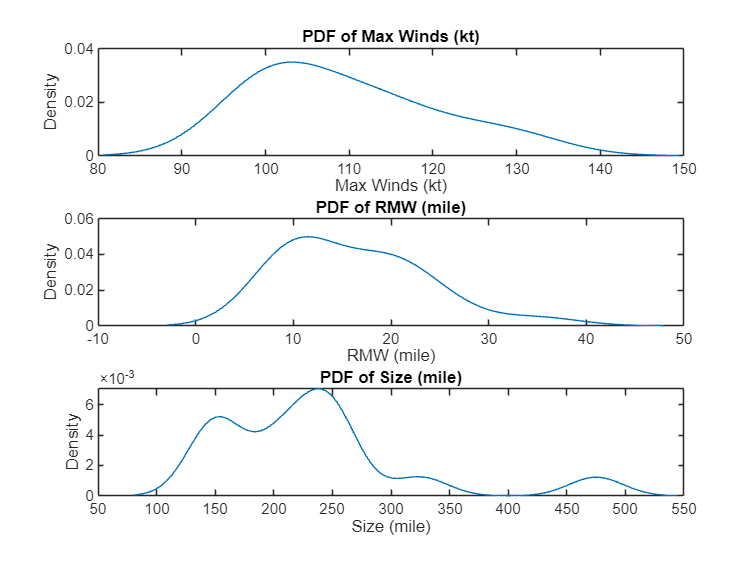


% Plot the PDFs
figure;
subplot(3,1,1);
plot(pdfs.MaxWinds.x, pdfs.MaxWinds.y);
title('PDF of Max Winds (kt)');
xlabel('Max Winds (kt)');
ylabel('Density');

subplot(3,1,2);
plot(pdfs.RMW.x, pdfs.RMW.y);
title('PDF of RMW (mile)');
xlabel('RMW (mile)');
ylabel('Density');

subplot(3,1,3);
plot(pdfs.Size.x, pdfs.Size.y);
title('PDF of Size (mile)');
xlabel('Size (mile)');
ylabel('Density');

simulation_conditions = struct();
simulation_conditions.initial_state = [28.9; % degrees North
                                      -95.2]; % degrees West
simulation_conditions.angles = [340, 330, 320]; % degrees
simulation_conditions.speed = 9; % miles per hour
simulation_conditions.time_steps = 0:12; % hours
simulation_conditions.N0 = 300; % Number of hurricane samples to generate
simulation_conditions.wind_speed_thresholds = [110,155];

%paths = generate_hurricane_paths(initial_state);
%disp(paths);

% Example usage
N0 = simulation_conditions.N0; % Number of hurricane samples to generate
hurricane_samples = simulate_hurricanes(N0,data,pdfs);

results = simulate_hurricane_landfall(data, pdfs, hurricane_samples, simulation_conditions);

node_1_location = [29.2038, -95.4245];
pole_interval = 50; %metre

[ieee_33, pole_num, line_num] = generate_ieee_33_bus(node_1_location, pole_interval);

%results = calculate_HIM_slow(results,simulation_conditions,ieee_33);
[Pr_out,times, hurricane_impact_matrix] = calculate_falling_probability(results,simulation_conditions,ieee_33);
%Pr_out_com = calculate_falling_probability_old(results, simulation_conditions, ieee_33);

line_failing_prob = calculate_line_failing_prob(Pr_out, pole_num, line_num,simulation_conditions.N0);
save('Pr_out.csv',"Pr_out");
save('line_failing_prob.mat',"line_failing_prob");